# Laboratoire 1

## Exercise 1

clc
clear
close all

load("/Users/francoisdesautels/Documents/GitHub/S5_APP3/DonneesIdentifSyst1erOrdre_1.mat");

dT = t(2);
diff_y = diff(y)/dT;

Y = y(1:end-1, 1);
X = [u(1:end-1, 1), diff_y];

A = pinv(X)*Y;


## Exercise 2

clc
clear
close all

sys1 = tf([2 6.4],[1 8]);
sys2 = tf([25], [1 14.8 61.7 47 25]);
sys3 = tf([3], [1 3]);

F = sys1 * sys2 * sys3;

%pzmap(F, 'red')
%grid

[Num Den] = tfdata(F, 'v');
[r, p, k] = residue(Num, Den);

poids = abs(r)./abs(real(p));

%Seulement avec les poids les plus gros
sys4 = tf([r(5)], [1 -p(5)]);

sys5 = tf([r(6)], [1 -p(6)]);


F2 = sys4 + sys5;

%Gain DC
DC1 = dcgain(F);
DC2 = dcgain(F2);
Gain = DC1/DC2;

%Afficher le step
[y1, t1] = step(F);
[y2, t2] = step(Gain*F2);


## Exercise 3

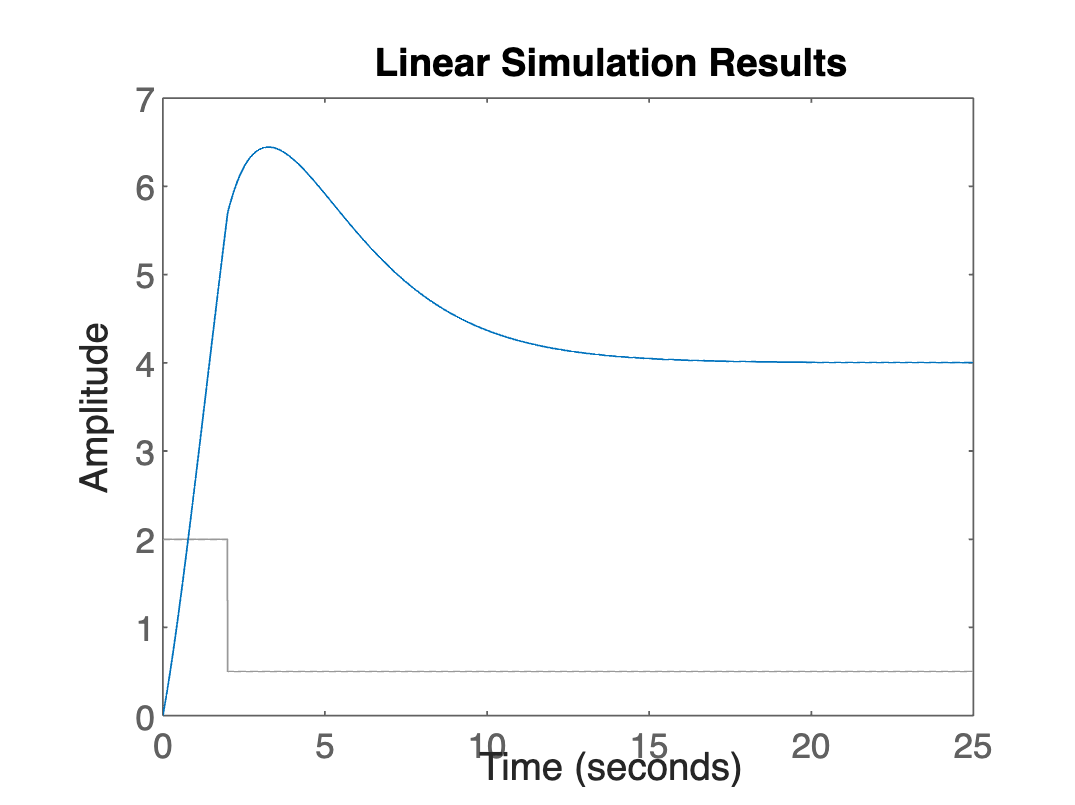

clc
clear
close all

t = [0:0.01:25];
u = zeros(size(t));
u((t >= 0) &(t < 2)) = 2;
u((t >= 2)) = 0.5;

[A B C D] = tf2ss([1 2], [1 1 0.25]);

sys = ss(A, B, C, D);
lsim(sys, u, t);

## Exercise 4

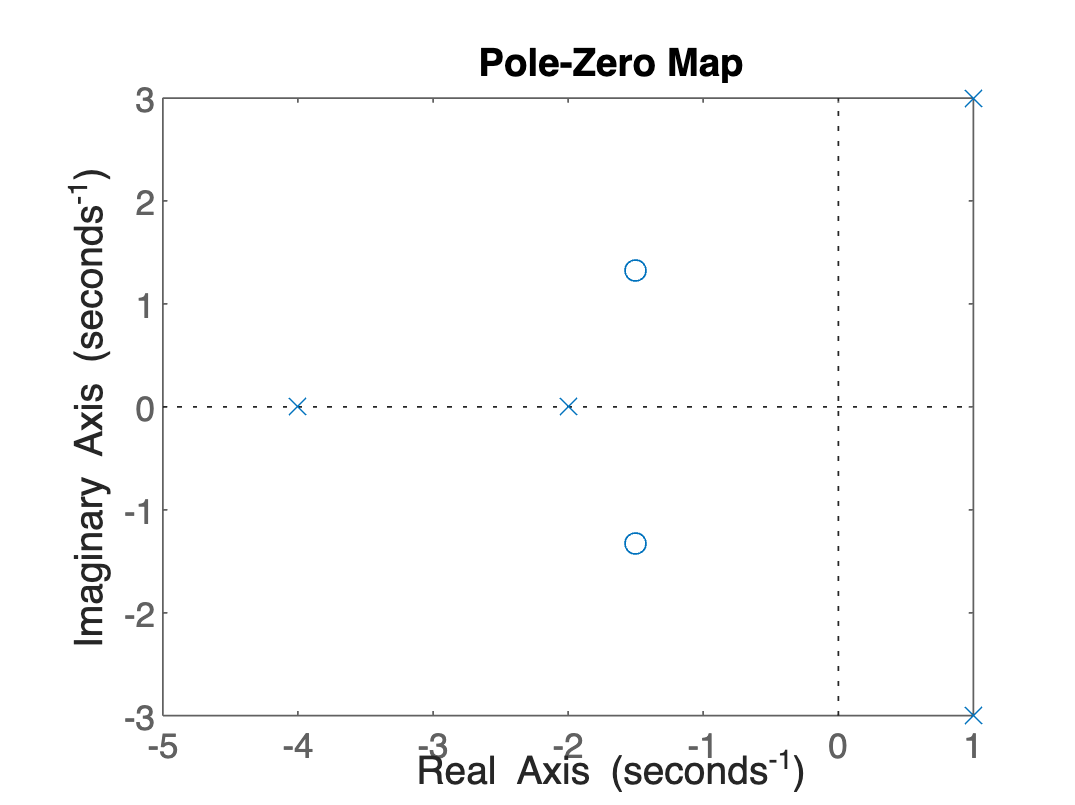

clc
clear
close all

sys1 = tf([1 3 4], [1 4 6 44 80]);

pzmap(sys1)

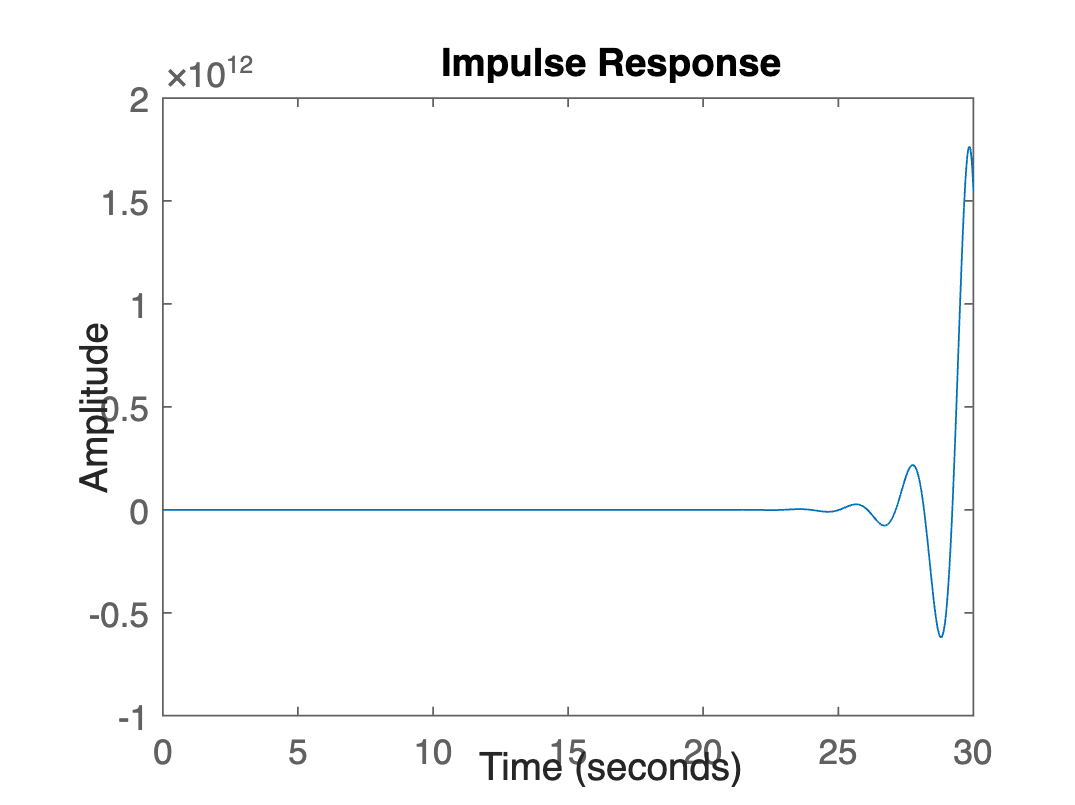

figure
impulse(sys1)

## Exercise 5

clc
clear
close all

t = [0:0.01:25];
u = zeros(size(t));
u((t >= 0) &(t <= 2)) = 2;
u((t >= 2)) = 0.5;

A = [-2  -2.5 -0.5;
      1    0    0;
      0    1    0];
B = [1;
     0;
     0];

B =      1
     0
     0


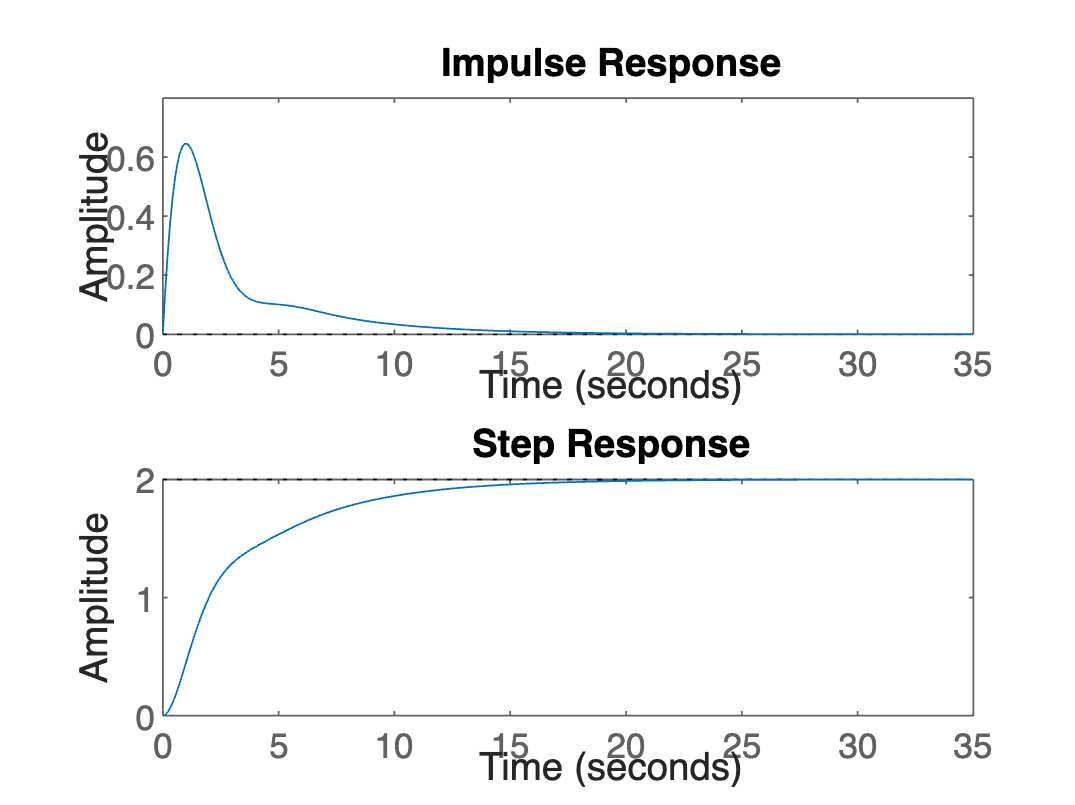

C = [0 1.5 1];
D = [0];

sys = ss(A, B, C, D);

%a
subplot(2, 1, 1)
impulse(sys)
hold on
subplot(2, 1, 2)
step(sys)

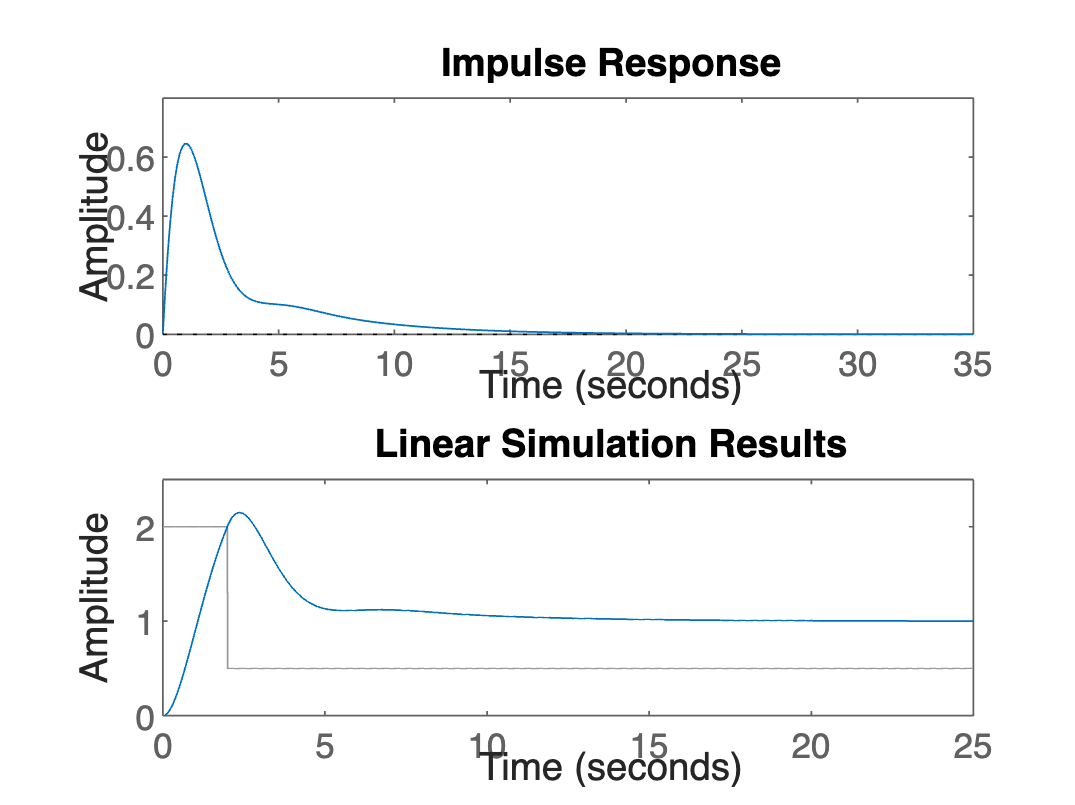

 Here is an example of how the function impulse works:
 Consider a randomly generated stable Transfer Function Model:
 of the form G(s)=num(s)/den(s):


num =          0   -0.1022    0.0316    0.1934   -0.1795    0.1620


den =     1.0000    6.2190   50.6538  222.7866  359.5180  162.7478


Call impulse using the following command (see also, help impulse):
impulse(tf(num,den));


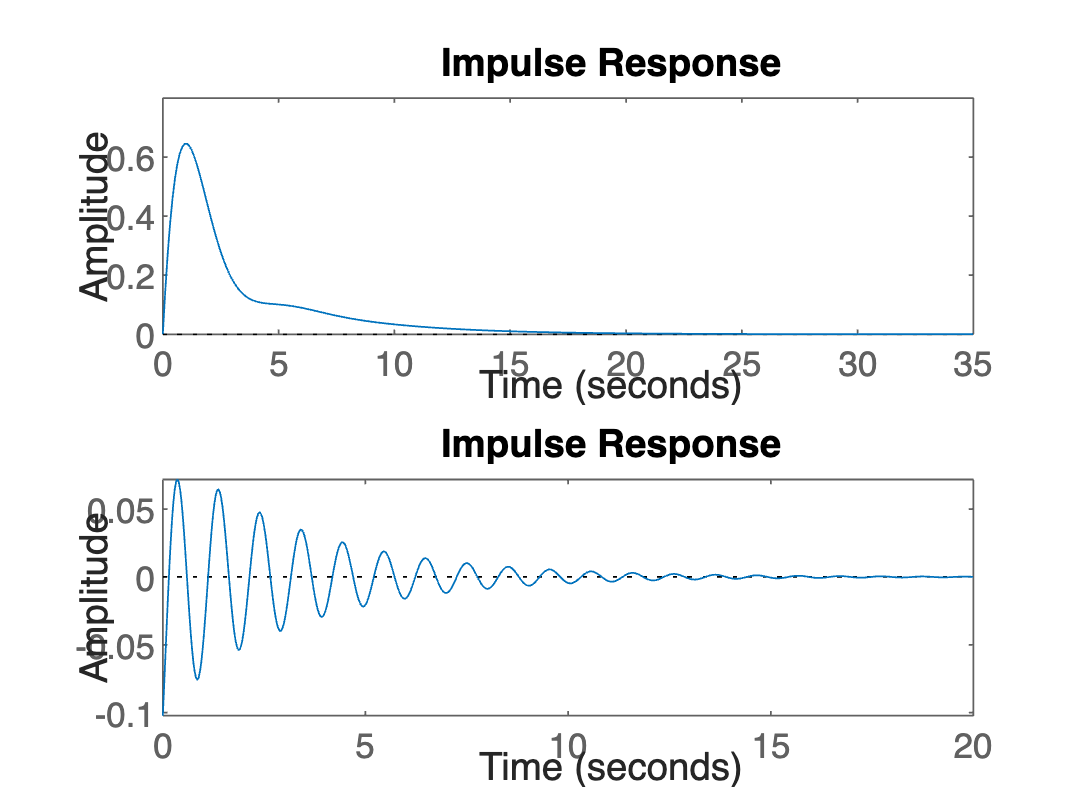


lsim(sys, u, t)